# Open Loop Analysis

## AFC Set UP

clear;
global fi_flag_Simulink
newline = sprintf('\n');
fc_afc = struct();
fc_afc.altitude = 10000;
fc_afc.velocity = 350;
FC_flag = 1; % Trim for steady wings-level flight
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees
disp('Trimming Low Fidelity Model AFC:');

Trimming Low Fidelity Model AFC:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 9.0255e-30
thrust = 2549.7407 lb
elev   = -3.8466 deg
ail    = -3.5741e-16 deg
rud    = -1.8619e-14 deg
alpha  = 8.8116 deg
dLEF   = 0 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo_AFC = linearize('LIN_F16Block');
long_states = [3 5 7 8 11 13 14];
long_inputs = [1 2];
long_outputs = [3 5 7 8 11];
SS_long_lo_AFC = ss(SS_lo_AFC.A(long_states,long_states), SS_lo_AFC.B(long_states,long_inputs), SS_lo_AFC.C(long_outputs,long_states), SS_lo_AFC.D(long_outputs,long_inputs));
SS_long_lo_AFC.StateName = SS_lo_AFC.StateName(long_states);
SS_long_lo_AFC.InputName= SS_lo_AFC.InputName(long_inputs);
lat_states = [4 6 7 9 10 12 13 15 16];
lat_inputs = [1 3 4];
lat_outputs = [4 6 7 9 10 12];
SS_lat_lo_AFC = ss(SS_lo_AFC.A(lat_states,lat_states), SS_lo_AFC.B(lat_states,lat_inputs), SS_lo_AFC.C(lat_outputs,lat_states), SS_lo_AFC.D(lat_outputs,lat_inputs));
SS_lat_lo_AFC.StateName = SS_lo_AFC.StateName(lat_states);
SS_lat_lo_AFC.InputName= SS_lo_AFC.InputName(lat_inputs);
disp(' ');

## Longitudinal State Space

disp('Longitudinal State Space');

Longitudinal State Space


lon_A = SS_long_lo_AFC.A;
lon_C = SS_long_lo_AFC.C;
lon_D = SS_long_lo_AFC.D;
lon_A;
lon_A(1,:) = [];
lon_A(:,1) = [];
lon_A(5:6,:) = [];
lon_A(:,5:6) = []

lon_A =          0         0         0    1.0000
  -32.1700   -0.0226   -7.1835   -2.3823
   -0.0000   -0.0005   -0.5261    0.9270
         0   -0.0000   -1.2333   -0.7914


lon_B = SS_long_lo_AFC.A(:,7);
lon_B(1,:) = [];
lon_B(5:6,:) = []

lon_B =          0
    0.0088
   -0.0011
   -0.0657


lon_C(1,:) = [];
lon_C(:,1) = [];
lon_C(:,5:6) = []

lon_C =    57.2958         0         0         0
         0    1.0000         0         0
         0         0   57.2958         0
         0         0         0   57.2958


lon_D(:,1) = [];
lon_D(1,:) = []

lon_D =      0
     0
     0
     0


disp(' ');

## Lateral State Space

disp('Lateral State Space');

Lateral State Space


lat_A = SS_lat_lo_AFC.A;
lat_C = SS_lat_lo_AFC.C;
lat_D = SS_lat_lo_AFC.D;
lat_A(2:3,:) = [];
lat_A(5:7,:) = [];
lat_A(:,2:3) = [];
lat_A(:,5:7) = []

lat_A =          0         0    1.0000    0.1550
    0.0908   -0.1660    0.1546   -0.9822
         0  -17.2449   -1.7173    0.7855
         0    3.4071   -0.0379   -0.2457


lat_B = SS_lat_lo_AFC.A(:,8:9);
lat_B(2:3,:) = [];
lat_B(5:7,:) = []

lat_B =          0         0
    0.0001    0.0004
   -0.2454   -0.0078
   -0.0128   -0.0284


lat_C(2:3,:) = [];
lat_C(:,2:3) = [];
lat_C(:,5:7) = []

lat_C =    57.2958         0         0         0
         0   57.2958         0         0
         0         0   57.2958         0
         0         0         0   57.2958


lat_D(:,1) = [];
lat_D(2:3,:) = []

lat_D =      0     0
     0     0
     0     0
     0     0


disp(' ');

## Longitudinal Motion

lon_sys = ss(lon_A,lon_B,lon_C,lon_D);
[w_n_lon,zeta_lon,p_lon] = damp(lon_sys);
disp('Short Period Characteristics');

Short Period Characteristics


pole_sp = p_lon(3:4)

pole_sp =   -0.6648 + 1.0567i
  -0.6648 - 1.0567i


n_freq_sp = w_n_lon(3)

n_freq_sp = 1.2484

zeta_sp = zeta_lon(3)

zeta_sp = 0.5325

P_sp = 2 *pi / imag(p_lon(3))

P_sp = 5.9460

T_half_sp = log(1/2) / real(pole_sp(1))

T_half_sp = 1.0427

disp(' ');

disp('Phugoid Characteristics');

Phugoid Characteristics


pole_ph = p_lon(1:2)

pole_ph =   -0.0053 + 0.1144i
  -0.0053 - 0.1144i


n_freq_ph = w_n_lon(1)

n_freq_ph = 0.1145

zeta_ph = zeta_lon(1)

zeta_ph = 0.0459

P_ph = 2 *pi / imag(p_lon(1))

P_ph = 54.9212

T_half_ph = log(1/2) / real(pole_ph(1))

T_half_ph = 131.7375

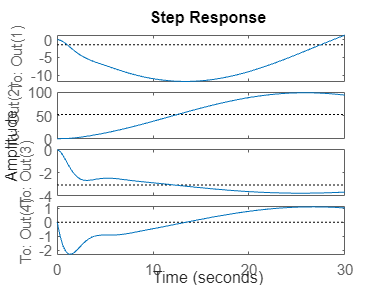

t = linspace(0,30,100);
step(lon_sys,t)

## Lateral Motion

lat_sys = ss(lat_A,lat_B,lat_C,lat_D);
[w_n_lat,zeta_lat,p_lat] = damp(lat_sys);
disp('Dutch Roll Characteristics');

Dutch Roll Characteristics


pole_dr = p_lat(3:4)

pole_dr =   -0.3532 + 2.3773i
  -0.3532 - 2.3773i


n_freq_dr = w_n_lat(3)

n_freq_dr = 2.4033

zeta_dr = zeta_lat(3)

zeta_dr = 0.1470

P_dr = 2 *pi / imag(p_lat(3))

P_dr = 2.6430

T_half_dr = log(1/2) / real(pole_dr(1))

T_half_dr = 1.9625

disp(' ');

disp('Aperiod Roll Characteristics');

Aperiod Roll Characteristics


pole_ap = p_lat(2)

pole_ap = -1.4165

n_freq_ap = w_n_lat(2)

n_freq_ap = 1.4165

T_constant_ap = -1/real(pole_ap)

T_constant_ap = 0.7060

T_half_ap = log(1/2) / real(pole_ap)

T_half_ap = 0.4893

disp(' ');

disp('Spiral Characteristics');

Spiral Characteristics


pole_spiral = p_lat(1)

pole_spiral = -0.0061

n_freq_spiral = w_n_lat(1)

n_freq_spiral = 0.0061

T_constant_spiral = -1/real(pole_spiral)

T_constant_spiral = 162.9035

T_half_spiral = log(1/2) / real(pole_spiral)

T_half_spiral = 112.9161

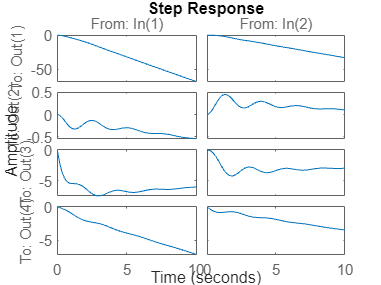

t = linspace(0,10,100);
step(lat_sys,t);